fig1 = [250 50 250 50 250; 50 250 50 250 50; 250 50 250 50 250; 50 250 50 250 50; 250 50 250 50 250]

fig1 =    250    50   250    50   250
    50   250    50   250    50
   250    50   250    50   250
    50   250    50   250    50
   250    50   250    50   250


fig1_a = imtranslate(fig1,[2,3])

fig1_a =      0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0   250    50   250
     0     0    50   250    50



fig1_b = imtranslate(fig1,[0,1])

fig1_b =      0     0     0     0     0
   250    50   250    50   250
    50   250    50   250    50
   250    50   250    50   250
    50   250    50   250    50


fig1_b1 = imrotate(fig1_b, 30)

fig1_b1 =      0     0     0     0     0     0     0
     0     0     0     0   250     0     0
     0     0   250    50   250    50     0
     0   250    50    50    50   250     0
     0    50   250    50   250   250    50
     0     0   250   250    50     0     0
     0     0    50     0     0     0     0


fig1_b12 = imresize(fig1_b1, [5,5])

fig1_b12 =     0.6782   -8.9898    7.4368   34.9175   -3.9117
   -7.7658   79.1157   97.4023  163.5189   -7.1897
   48.9655  157.2079   55.0155  178.0102   70.6254
   -4.7559  164.1363  177.8023  161.7296   57.1246
   -5.8865   57.1246   70.6254   -7.0757   -5.8865



fig1_c = imtranslate(fig1,[2,3])

fig1_c =      0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0   250    50   250
     0     0    50   250    50


fig1_c1 = imrotate(fig1_c, 30)

fig1_c1 =      0     0     0     0     0     0     0
     0     0     0     0     0     0     0
     0     0     0     0     0     0     0
     0     0     0     0    50   250     0
     0     0     0     0   250   250    50
     0     0     0     0    50     0     0
     0     0     0     0     0     0     0


fig1_c2 = imrotate(fig1_c1, 60)

fig1_c2 =      0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0    50     0     0
     0     0     0     0     0   250   250    50     0     0
     0     0     0     0     0    50   250     0     0     0
     0     0     0     0     0     0     0    50     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0


fig1_c3 = imrotate(fig1_c2, 90)

fig1_c3 =      0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0    50    50     0    50     0     0     0     0
     0     0     0   250   250     0     0     0     0     0
     0     0     0   250    50     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0


fig1_c4 = imresize(fig1_c3, [5,5])

fig1_c4 =     0.8591   -1.9180   -2.7939    0.9827   -0.0595
   -4.7035   90.2397   76.0384   -3.4103   -0.2541
   -5.5092   63.4819   36.2679   -3.5385    0.0206
    0.4669   -5.6122   -3.3600    0.3021         0
         0         0         0         0         0




%Prepping the image
img1 = fig1_a;

%Getting object ready
hbm = vision.BlockMatcher('ReferenceFrameSource',...
        'Input port','BlockSize',[5 5]);
    
hbm.OutputValue = 'Horizontal and vertical components in complex form';
halphablend = vision.AlphaBlender;

%Prepping comparison image
img2 = fig1;

%Calculate motion
motion = hbm(img1,img2);

%Merge images
img13 = halphablend(img2,img1);

%Show and plot motion
[X,Y] = meshgrid(1:35:size(img1,2),1:35:size(img1,1));         
img13

img13 =    62.5000   12.5000   62.5000   12.5000   62.5000
   12.5000   62.5000   12.5000   62.5000   12.5000
   62.5000   12.5000   62.5000   12.5000   62.5000
   12.5000   62.5000  200.0000  100.0000  200.0000
   62.5000   12.5000  100.0000  200.0000  100.0000


hold on
quiver(X(:),Y(:),real(motion(:)),imag(motion(:)),0)
hold off

%Prepping the image
img1 = fig1_b12;

%Getting object ready
hbm = vision.BlockMatcher('ReferenceFrameSource',...
        'Input port','BlockSize',[5 5]);
    
hbm.OutputValue = 'Horizontal and vertical components in complex form';
halphablend = vision.AlphaBlender;

%Prepping comparison image
img2 = fig1;

%Calculate motion
motion = hbm(img1,img2);

%Merge images
img14 = halphablend(img2,img1);

%Show and plot motion
[X,Y] = meshgrid(1:35:size(img1,2),1:35:size(img1,1));         
img14

img14 =    63.0086    5.7576   68.0776   38.6882   59.5662
    6.6756  121.8368   85.5517  185.1392    7.1077
   99.2241  130.4059  103.7617  146.0077  115.4691
    8.9331  185.6022  145.8517  183.7972   55.3434
   58.0851   55.3434  115.4691    7.1932   58.0851


hold on
quiver(X(:),Y(:),real(motion(:)),imag(motion(:)),0)
hold off

%Prepping the image
img1 = fig1_c4;

%Getting object ready
hbm = vision.BlockMatcher('ReferenceFrameSource',...
        'Input port','BlockSize',[5 5]);
    
hbm.OutputValue = 'Horizontal and vertical components in complex form';
halphablend = vision.AlphaBlender;

%Prepping comparison image
img2 = fig1;

%Calculate motion
motion = hbm(img1,img2);

%Merge images
img15 = halphablend(img2,img1);

%Show and plot motion
[X,Y] = meshgrid(1:35:size(img1,2),1:35:size(img1,1));         
img15

img15 =    63.1443   11.0615   60.4046   13.2370   62.4554
    8.9724  130.1798   69.5288   59.9422   12.3095
   58.3681   60.1114   89.7009    9.8461   62.5154
   12.8502   58.2909    9.9800   62.7266   12.5000
   62.5000   12.5000   62.5000   12.5000   62.5000


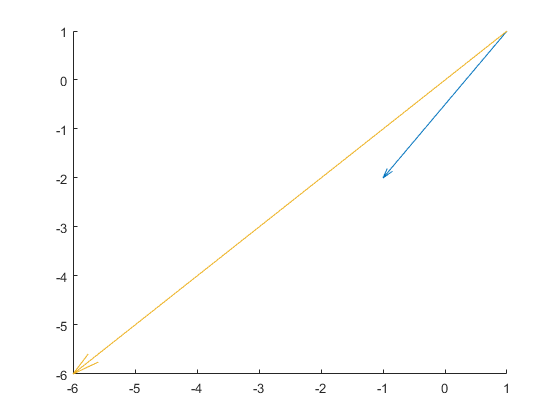

hold on
quiver(X(:),Y(:),real(motion(:)),imag(motion(:)),0)
hold off